## Robotics System Toolbox II

The 'Run section' Button could be helpful for solving this lab.

### ROS Publisher

**1)** Launch the Turtlebot Gazebo simulation in ROS from the ubuntu command line with the world file. Spawn the turtlebot at a position outside of the box to move the robot in free space without collisions.

**2)** Shutdown the current connection to the ROS master in Matlab with `rosshutdown` in case the current master is still running. Reconnect with `rosinit` to the new master.

clear all; close all; clc;
rosshutdown

Shutting down global node /matlab_global_node_93977 with NodeURI http://192.168.2.111:63724/


rosinit('http://ubuntu:11311/')

Initializing global node /matlab_global_node_85188 with NodeURI http://192.168.2.111:63866/


**3)** Create a publisher `velPub` for the `/cmd_vel` topic. Create an empty message `velMsg` for that topic either with `rosmessage` or directly with `rospublisher`. Set the X-component of linear velocity field of the` velMsg.Linear.X` to 0.2 m/s. Publish the message `velMsg` with the command `send`. The robot should start moving in a straight line. Stop the robot by sending a new message with zero linear velocity.

[velPub, velMsg] = rospublisher('/cmd_vel', 'geometry_msgs/Twist');
velMsg.Linear.X = 0.2;
send(velPub, velMsg);

pause(3);

velMsg.Linear.X = 0;
send(velPub, velMsg);

**4)** Write a function `forward` (at the bottom of this script) that moves the robot in a straight line for a specified distance `distance` at a specifified linear velocity `velocity`. The input argument `velPub` denotes the publisher.

**5)** Write a similar function `turn` (at the bottom of this script) that turns the robot on the spot for an `angle` $\theta$ at a `turnrate` $\omega$. Move the robot with the `forward` and `turn` functions.

turn(velPub, 5, 3)
forward(velPub, 5, 1.5)

### ROS Actions

**6)** The move_base action is provided by the ROS Navigation Stack. Launch the Navigation Stack in a second ubuntu terminal with:

Display the current list of actions on the ROS network. Confirm that there is an action `/move_base`.

rosaction list

/move_base


**7)** Instantiate an action client `actClient` and an empty goal message `goalMsg` for the action `/move_base`. Set the properties `FeedbackFcn` and `ResultFcn` of the `actClient` to `[]`.

[actClient, goalMsg] = rosactionclient('/move_base');
actClient.FeedbackFcn = [];
actClient.ResultFcn = [];

**8)** Inspect the structure of the `goalMsg` which is of type `move_base_msgs/MoveBaseGoal`. Modify the goal position, orientation and map frame id.

goalMsg.showdetails


  TargetPose    
    Header    
      Stamp      
        Sec  :  0
        Nsec :  0
      Seq     :  0
      FrameId :  
    Pose      
      Position       
        X :  0
        Y :  0
        Z :  0
      Orientation    
        X :  0
        Y :  0
        Z :  0
        W :  0


goalMsg.TargetPose.Pose.Position.X = 7.0;
goalMsg.TargetPose.Pose.Position.Y = 7.0;
goalMsg.TargetPose.Pose.Orientation.W = pi;
goalMsg.TargetPose.Header.FrameId = 'map';

**9)** Send the modified goal message `goalMsg` with the action client `actClient` and the `sendGoal` function observe the command line output of the activation, feedback and result callback functions.

sendGoal(actClient, goalMsg);

**10)** Send another modified goal message `goalMsg` with a remote goal pose. Cancel the goal while the goal was not completed yet.

goalMsg.TargetPose.Pose.Position.X = 2.5;
goalMsg.TargetPose.Pose.Position.Y = 2.5;
goalMsg.TargetPose.Pose.Orientation.W = pi/2;
goalMsg.TargetPose.Header.FrameId = 'map';

sendGoal(actClient, goalMsg)
pause(5)
cancelGoal(actClient);

**11)** Write a function `squarepath` which moves the robot along a square at the bottom of this script. Utilize the function here to drive the robot in a square path.

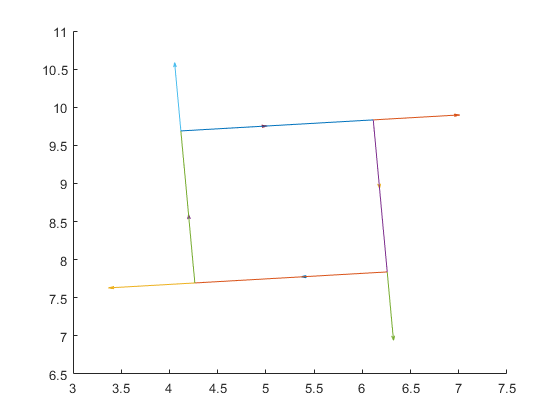

%test code
% odomSub = rossubscriber('/odom', 'nav_msgs/Odometry');
% odomMsg = receive(odomSub);
% odomMsg.showdetails

squarepath(actClient, 2);

#### Function Definitions

**4)** Write a function `forward` that moves the robot in a straight line for a specified distance `distance` at a specified linear velocity `velocity `at the bottom of this script. The input argument `velPub` denotes the publisher.

The distance traveled by the robot is controlled in an open loop fashion by dead reckoning as product of commanded velocity and time. The forward motion with the command velocity executes for a time interval $t=\frac{d}{v}$ seconds. Utilize a rate object with a rate that is inverse proportional to that time interval.

function forward(velPub, distance, velocity)
    % function makes turtlebot drive straight with the velocity "velocity" for
    % the distance "distance" by send message to topic "velPub"
    
    % create velocity message from topic velPub
    velMsg = rosmessage(velPub);
    % set Speed in x-direction to "velocity"
    velMsg.Linear.X = velocity;
    velMsg.Angular.Z = 0;
    % send message to robot
    send(velPub, velMsg);
    % wait until robot made the full direction 
    rateObj = robotics.Rate(velocity/distance);
    rateObj.reset;
    waitfor(rateObj);
    % send new message with a velocity of 0 m/s to make it stop
    velMsg.Linear.X = 0;
    send(velPub, velMsg);
end

**5)** Write a similar function `turn` that turns the robot on the spot for an `angle` $\theta$ at a `turnrate` $\omega$. The angle $\theta$ traveled by the robot is controlled in an open loop fashion by dead reckoning. The turn motion lasts for $t=\frac{|\theta |}{\omega \;}$seconds. Ensure the correct sign of the turn rate `turnrate` for clockwise and counterclockwise rotations.

function turn( velPub, angle, turnrate )
    %Function turns the robot on the spot for an angle "angle" at a turnrate
    %"turnrate" by publishing omega to velPub
    
    % create velocity message from topic velPub
    velMsg = rosmessage(velPub);
    % set Speed in x-direction to "velocity"
    velMsg.Angular.Z = turnrate;
    % send message to robot
    send(velPub, velMsg);
    % wait until robot made the full direction 
    rateObj = robotics.Rate(turnrate/angle);
    waitfor(rateObj);
    % send new message with a turnrate of 0 rad/s to make it stop
    velMsg.Linear.X = 0;
    velMsg.Angular.Z = 0;
    send(velPub, velMsg);
end


**11)** Write a function squarepath which moves the robot along a square of side length `sidelength` by a sequence of four straight line motions and right angle turns as shown below.

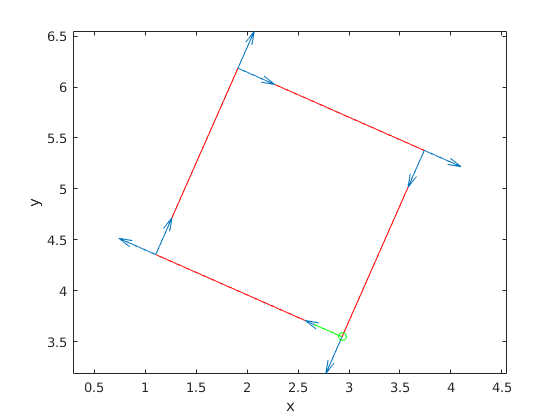

Implement the function with an action client rather than with direct velocity commands. In that case you are supposed to use `sendGoalAndWait` in order not to overwrite a goal that is still active. Since the commanded movement of `squarepath` is relative to the current pose, first determine the current pose by subscribing to the topic `/odom`. Be aware that there is an offset of $\left\lbrack \Delta x,\Delta y\right\rbrack =\left\lbrack 2,2\right\rbrack$ between the `odom` and `map` frame which you have to add to determine the goal pose from the odom pose. Calculate the intermediate poses according to the side length of the square. Notice that there eight intermediate goals, four for the forward motion and four for the right angle turn. Your function sends the corresponding eight goal messages in that order to the action server. For the sake of convenience the function Pose2GoalMsg is provided below which converts a pose into a message of type `move_base_msgs/MoveBaseGoal`. The function OdometryMsg2Pose which you developed in the Robotics System Toolbox I Lab is provided as well.

function squarepath(actClient, sidelength)
    %Function makes robot defined in actClient drive a square with the
    %sidelength "sidelength"
    
    odomSub = rossubscriber('/odom', 'nav_msgs/Odometry');
    odomMsg = receive(odomSub);
    
    % array of goal poses
    goals = cell(1,8);
    [x_r, y_r, theta_r] = OdometryMsg2Pose(odomMsg);
    x_r = x_r + 2;
    y_r = y_r + 2;
    
    figure;
    for i = 1:2:7
        %plot the intermediate pose
        hold on;
        
        % In Gazebo, the x-axis is y and the y-axis is x.
        quiver(x_r, y_r, sin(theta_r), cos(theta_r));
        
        %calculate the forward goal
        xr_temp = x_r + sidelength*sin(theta_r);
        yr_temp = y_r + sidelength*cos(theta_r);
        goalMsg_FWD = Pose2GoalMsg(xr_temp, yr_temp, theta_r);
        goals{i} = goalMsg_FWD;
        
        %plot the travelled edge of the square
        x = linspace(x_r, xr_temp, 10);
        y = linspace(y_r, yr_temp, 10);
        plot(x,y);
        
        %plot the intermediate pose
        quiver(xr_temp, yr_temp, sin(theta_r), cos(theta_r));
        
        %calculate the turn goal
        thetar_temp = theta_r + (pi/2);
        goalMsg_TRN = Pose2GoalMsg(xr_temp, yr_temp, thetar_temp);
        goals{i+1} = goalMsg_TRN;
        
        %reset the pose
        theta_r = thetar_temp;
        x_r = xr_temp;
        y_r = yr_temp;
    end
        
    %send the goals and wait
    for j = 1:8
        sendGoalAndWait(actClient, goals{j});
    end
end

#### Helper Functions

function [ goalMsg ] = Pose2GoalMsg( x, y, theta )
    % convert vector to pose stamped message
    goalMsg=rosmessage('move_base_msgs/MoveBaseGoal');
    
    goalMsg.TargetPose.Pose.Position.X=x;
    goalMsg.TargetPose.Pose.Position.Y=y;
    goalMsg.TargetPose.Pose.Position.Z=0;
    
    q=eul2quat([theta, 0, 0]);
    goalMsg.TargetPose.Pose.Orientation.W=q(1);
    goalMsg.TargetPose.Pose.Orientation.X=q(2);
    goalMsg.TargetPose.Pose.Orientation.Y=q(3);
    goalMsg.TargetPose.Pose.Orientation.Z=q(4);
    
    goalMsg.TargetPose.Header.FrameId='map';
end


function [ x, y, theta ] = OdometryMsg2Pose( odomMsg )
    % converts odometry message to vector
    x = odomMsg.Pose.Pose.Position.X;
    y = odomMsg.Pose.Pose.Position.Y;
    
    eta = odomMsg.Pose.Pose.Orientation.W;
    epsilonx = odomMsg.Pose.Pose.Orientation.X;
    epsilony = odomMsg.Pose.Pose.Orientation.Y;
    epsilonz = odomMsg.Pose.Pose.Orientation.Z;
        
    eul=quat2eul([eta, epsilonx, epsilony, epsilonz]);
    theta=eul(1);
end